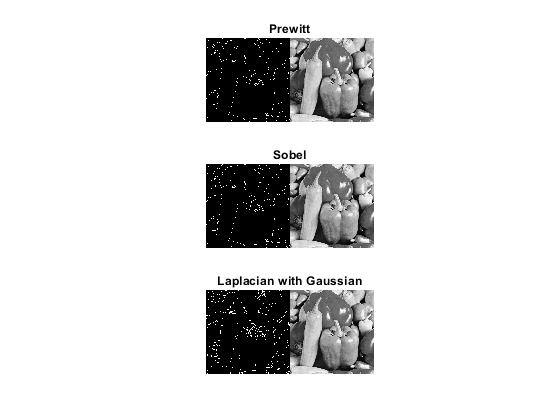

% Peppers Color is in a strange format. CData + Colormap
[peppers, map] = imread('peppers_color.tif');
if ~isempty(map)
    peppers = ind2rgb(peppers(:,:,1),map);
end

% Empty 3x3 Kernel
% [a b c;
%  d e f; 
%  g h i ];
my_empty_kernel = [ 0 0 0; 1 0 -1; 0 0 0 ];

prewit_x_horizontal = [ -1 0 1; -1 0 1; -1 0 1 ];
prewit_y_vertical = [ -1 -1 -1; 0 0 0; 1 1 1 ];

sobel_x_horizontal = [ -1 0 1; -2 0 2; -1 0 1 ];
sobel_y_vertical = [ -1 -2 -1; 0 0 0; 1 2 1 ];

first_derivitave_x_pos = [0 0 0; -1 0 1; 0 0 0];

laplaction_kernel = [ 0 1 0; 1 -4 1; 0 1 0 ]; 

% Conversion to greyscale produces a double 0->1. 
% Scale this to 0->255
% Convert to uint8 for display.
%peppers_grey = uint8(rgb2gray(peppers)*255);
%peppers_hsv = uint8(rgb2hsv(peppers));

%imshowpair(peppers,peppers_grey,'montage');
%imshowpair(r, g, 'montage');
%imshow(peppers_grey);

% W4 starts here

[lena, map] = imread('lena_color_512.tif');
if ~isempty(map)
    lena = ind2rgb(lena(:,:,1), map);
end

%lena_grey = uint8(rgb2gray(lena)*255);
%lena_hsv = uint8(rgb2hsv(lena));

displaySobelPrewitt(peppers);

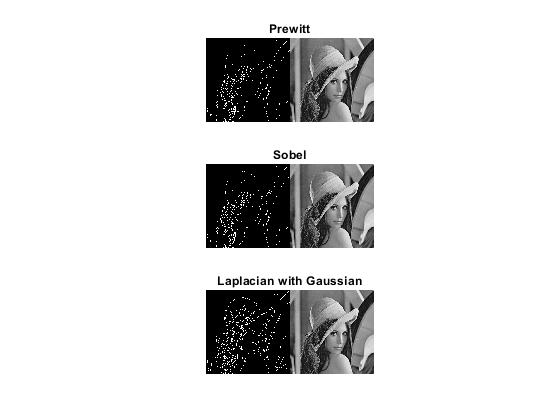

displaySobelPrewitt(lena)

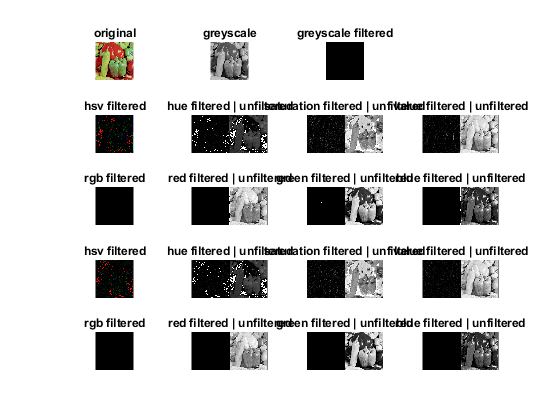


displayInFigure(peppers);

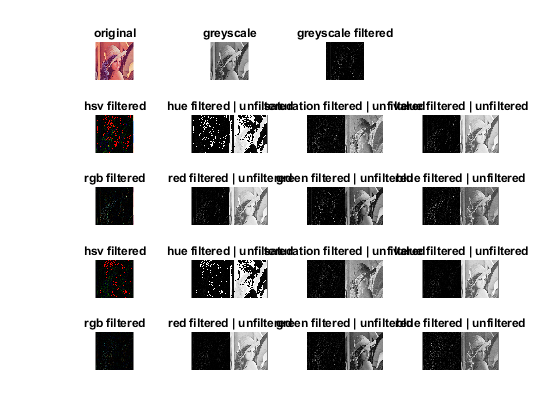

displayInFigure(lena);



% Functions

function [r, g, b, rgb, ro, go, bo] = rgbFirstDerivFilter(orig)
    
    first_derivitave_x_pos = [0 0 0; -1 0 1; 0 0 0];

    % 1. channel split
    red = orig(:,:,1); % Redchannel
    green = orig(:,:,2); % Greenchannel
    blue = orig(:,:,3); % Bluechannel
    black = zeros(size(orig,1), size(orig,2), 'uint8');
    
    % 2. first derivative Convolution filter channels
    redout = uint8(conv2(red,first_derivitave_x_pos));
    greenout = uint8(conv2(green,first_derivitave_x_pos));
    blueout = uint8(conv2(blue,first_derivitave_x_pos));
    
    % 3. channels recombined
    recombined = cat(3, redout, greenout, blueout);
    
    ro = red;
    go = green;
    bo = blue;
    r = redout;
    g = greenout;
    b = blueout;
    rgb = recombined;

end

function [r, g, b, rgb, ro, go, bo] = rgbSecondDerivFilter(orig)
    
    second_derivitave_x_pos = [0 0 0; 0 1 -1; 0 0 0];

    % 1. channel split
    red = orig(:,:,1); % Redchannel
    green = orig(:,:,2); % Greenchannel
    blue = orig(:,:,3); % Bluechannel
    black = zeros(size(orig,1), size(orig,2), 'uint8');
    
    % 2. first derivative Convolution filter channels
    redout = uint8(conv2(red,second_derivitave_x_pos));
    greenout = uint8(conv2(green,second_derivitave_x_pos));
    blueout = uint8(conv2(blue,second_derivitave_x_pos));
    
    % 3. channels recombined
    recombined = cat(3, redout, greenout, blueout);
    
    ro = red;
    go = green;
    bo = blue;
    r = redout;
    g = greenout;
    b = blueout;
    rgb = recombined;

end

function [h, s, v, hsv, ho, so, vo] = hsvFirstDerivFilter(orig)
    
    first_derivitave_x_pos = [0 0 0; -1 0 1; 0 0 0];

    % 1. channel split
    one = orig(:,:,1); % Hue
    two = orig(:,:,2); % Saturation
    three = orig(:,:,3); % Value
    black = zeros(size(orig,1), size(orig,2), 'uint8');
    
    % 2. first derivative Convolution filter channels
    oneout = uint8(conv2(one,first_derivitave_x_pos));
    twoout = uint8(conv2(two,first_derivitave_x_pos));
    threeout = uint8(conv2(three,first_derivitave_x_pos));
    
    % 3. channels recombined
    recombined = cat(3, oneout, twoout, threeout);
    
    ho = one;
    so = two;
    vo = three;
    h = oneout;
    s = twoout;
    v = threeout;
    hsv = recombined;

end

function [h, s, v, hsv, ho, so, vo] = hsvSecondDerivFilter(orig)
    
    second_derivitave_x_pos = [0 0 0; 0 1 -1; 0 0 0];

    % 1. channel split
    one = orig(:,:,1); % Hue
    two = orig(:,:,2); % Saturation
    three = orig(:,:,3); % Value
    black = zeros(size(orig,1), size(orig,2), 'uint8');
    
    % 2. first derivative Convolution filter channels
    oneout = uint8(conv2(one,second_derivitave_x_pos));
    twoout = uint8(conv2(two,second_derivitave_x_pos));
    threeout = uint8(conv2(three,second_derivitave_x_pos));
    
    % 3. channels recombined
    recombined = cat(3, oneout, twoout, threeout);
    
    ho = one;
    so = two;
    vo = three;
    h = oneout;
    s = twoout;
    v = threeout;
    hsv = recombined;

end

function c = greyFirstDerivFilter(orig)

    first_derivitave_x_pos = [0 0 0; -1 0 1; 0 0 0];
    
    out = uint8(conv2(orig,first_derivitave_x_pos));
    
    c = out;

end

function c = greySecondDerivFilter(orig)

    second_derivitave_x_pos = [0 0 0; 0 1 -1; 0 0 0];
    
    out = uint8(conv2(orig,second_derivitave_x_pos));
    
    c = out;

end

function [r, g, b, rgb, ro, go, bo] = rgbFilter(orig, kernel)

    % 1. channel split
    red = orig(:,:,1); % Redchannel
    green = orig(:,:,2); % Greenchannel
    blue = orig(:,:,3); % Bluechannel
    black = zeros(size(orig,1), size(orig,2), 'uint8');
    
    % 2. first derivative Convolution filter channels
    redout = uint8(conv2(red,kernel));
    greenout = uint8(conv2(green,kernel));
    blueout = uint8(conv2(blue,kernel));
    
    % 3. channels recombined
    recombined = cat(3, redout, greenout, blueout);
    
    ro = red;
    go = green;
    bo = blue;
    r = redout;
    g = greenout;
    b = blueout;
    rgb = recombined;

end

function [h, s, v, hsv, ho, so, vo] = hsvFilter(orig, kernel)

    % 1. channel split
    one = orig(:,:,1); % Hue
    two = orig(:,:,2); % Saturation
    three = orig(:,:,3); % Value
    black = zeros(size(orig,1), size(orig,2), 'uint8');
    
    % 2. first derivative Convolution filter channels
    oneout = uint8(conv2(one,kernel));
    twoout = uint8(conv2(two,kernel));
    threeout = uint8(conv2(three,kernel));
    
    % 3. channels recombined
    recombined = cat(3, oneout, twoout, threeout);
    
    ho = one;
    so = two;
    vo = three;
    h = oneout;
    s = twoout;
    v = threeout;
    hsv = recombined;

end

function c = greyFilter(orig, kernel)
    
    out = uint8(conv2(orig,kernel));
    
    c = out;

end

function f = displaySobelPrewitt(orig)

    gray = rgb2gray(orig);
    
    prewitt = edge(gray, 'Prewitt');
    sobel = edge(gray, 'Sobel');
    laplacian = edge(gray, 'log');

    figure
    hold on;

    subplot(3,1,1);
    imshowpair(prewitt,gray,'montage');
    title('Prewitt');
    subplot(3,1,2);
    imshowpair(sobel,gray,'montage');
    title('Sobel');
    subplot(3,1,3);
    imshowpair(laplacian,gray,'montage');
    title('Laplacian with Gaussian');

    hold off;

end

function displayInFigure(orig)

    % orig = original image
    
    prewit_x_horizontal = [ -1 0 1; -1 0 1; -1 0 1 ];
    prewit_y_vertical = [ -1 -1 -1; 0 0 0; 1 1 1 ];

    sobel_x_horizontal = [ -1 0 1; -2 0 2; -1 0 1 ];
    sobel_y_vertical = [ -1 -2 -1; 0 0 0; 1 2 1 ];

    first_derivitave_x_pos = [0 0 0; -1 0 1; 0 0 0];

    laplaction_kernel = [ 0 1 0; 1 -4 1; 0 1 0 ]; 
    
    % step 1 get the images
    
    greyOrig = rgb2gray(orig);
    hsvOrig = uint8(rgb2hsv(orig)*255);
    
    [h, s, v, hsv, ho, so, vo] = hsvFirstDerivFilter(hsvOrig);
    [r, g, b, rgb, ro, go, bo] = rgbFirstDerivFilter(orig);
    grey = greyFirstDerivFilter(greyOrig);
    [h2, s2, v2, hsv2, ho2, so2, vo2] = hsvSecondDerivFilter(hsvOrig);
    [r2, g2, b2, rgb2, ro2, go2, bo2] = rgbSecondDerivFilter(orig);
    grey2 = greySecondDerivFilter(greyOrig);
    
    [prewit_x_h, prewit_x_s, prewit_x_v, prewit_x_hsv, prewit_x_ho, prewit_x_so, prewit_x_vo] = hsvFilter(hsvOrig, prewit_x_horizontal);
    [prewit_y_h, prewit_y_s, prewit_y_v, prewit_y_hsv, prewit_y_ho, prewit_y_so, prewit_y_vo] = hsvFilter(hsvOrig, prewit_y_vertical);
    [sobel_x_h, sobel_x_s, sobel_x_v, sobel_x_hsv, sobel_x_ho, sobel_x_so, sobel_x_vo] = hsvFilter(hsvOrig, sobel_x_horizontal);
    [sobel_y_h, sobel_y_s, sobel_y_v, sobel_y_hsv, sobel_y_ho, sobel_y_so, sobel_y_vo] = hsvFilter(hsvOrig, sobel_y_vertical);
    [first_deriv_h, first_deriv_s, first_deriv_v, first_deriv_hsv, first_deriv_ho, first_deriv_so, first_deriv_vo] = hsvFilter(hsvOrig, first_derivitave_x_pos);
    [lap_h, lap_s, lap_v, lap_hsv, lap_ho, lap_so, lap_vo] = hsvFilter(hsvOrig, laplaction_kernel);
    
    % step 2 put images in the figures
    
    figure
    hold on;
    
    subplot(5,4,1);
    imshow(orig);
    title('original');
    subplot(5,4,2);
    imshow(greyOrig);
    title('greyscale');
    subplot(5,4,3);
    imshow(grey);
    title('greyscale filtered');
    
    subplot(5,4,5);
    imshow(hsv);
    title('hsv filtered');
    subplot(5,4,6);
    imshowpair(h,ho,'montage');
    title('hue filtered | unfiltered');
    subplot(5,4,7);
    imshowpair(s,so,'montage');
    title('saturation filtered | unfiltered');
    subplot(5,4,8);
    imshowpair(v,vo,'montage');
    title('value filtered | unfiltered');
    
    subplot(5,4,9);
    imshow(rgb);
    title('rgb filtered');
    subplot(5,4,10);
    imshowpair(r,ro,'montage');
    title('red filtered | unfiltered');
    subplot(5,4,11);
    imshowpair(g,go,'montage');
    title('green filtered | unfiltered');
    subplot(5,4,12);
    imshowpair(b,bo,'montage');
    title('blue filtered | unfiltered');
    
    subplot(5,4,13);
    imshow(hsv2);
    title('hsv filtered');
    subplot(5,4,14);
    imshowpair(h2,ho2,'montage');
    title('hue filtered | unfiltered');
    subplot(5,4,15);
    imshowpair(s2,so2,'montage');
    title('saturation filtered | unfiltered');
    subplot(5,4,16);
    imshowpair(v2,vo2,'montage');
    title('value filtered | unfiltered');
    
    subplot(5,4,17);
    imshow(rgb2);
    title('rgb filtered');
    subplot(5,4,18);
    imshowpair(r2,ro2,'montage');
    title('red filtered | unfiltered');
    subplot(5,4,19);
    imshowpair(g2,go2,'montage');
    title('green filtered | unfiltered');
    subplot(5,4,20);
    imshowpair(b2,bo2,'montage');
    title('blue filtered | unfiltered');
    
    
    hold off;

end



